cd 'C:\Users\Ansh Singal\Desktop\study\ML\machine-learning-ex2\ex2'

load ex2data2.txt
aa = ex2data2

aa =     0.0513    0.6996    1.0000
   -0.0927    0.6849    1.0000
   -0.2137    0.6923    1.0000
   -0.3750    0.5022    1.0000
   -0.5132    0.4656    1.0000
   -0.5248    0.2098    1.0000
   -0.3980    0.0344    1.0000
   -0.3059   -0.1923    1.0000
    0.0167   -0.4042    1.0000
    0.1319   -0.5139    1.0000


y = aa(:, 3)

y =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


pos = find(aa(:,3)==1)

pos =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


neg = find(aa(:,3)==0)

neg =     59
    60
    61
    62
    63
    64
    65
    66
    67
    68


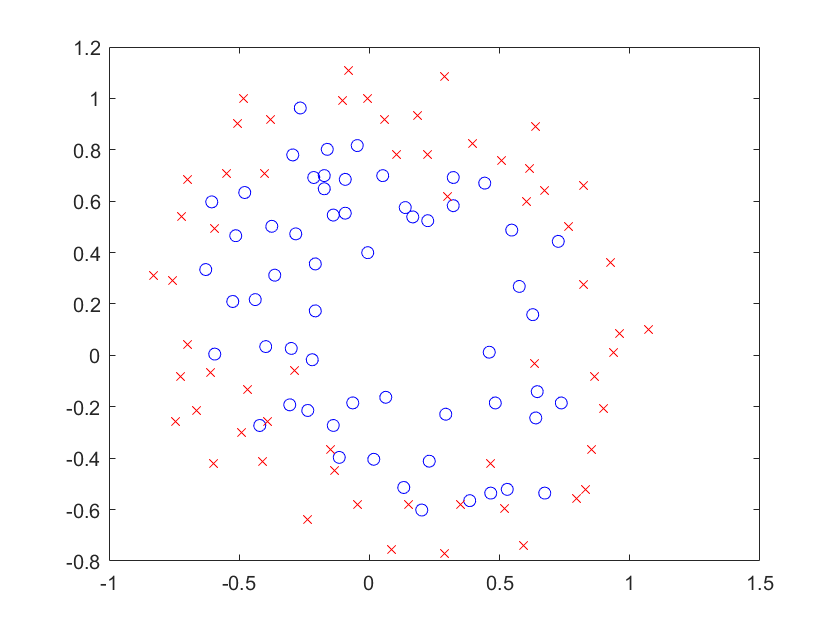

plot(aa(pos, 1), aa(pos, 2), 'bo')
hold on
plot(aa(neg, 1), aa(neg, 2), 'rx')
hold on

X = mapFeature(aa(:,1), aa(:,2))

X =     1.0000    0.0513    0.6996    0.0026    0.0359    0.4894    0.0001    0.0018    0.0251    0.3424    0.0000    0.0001    0.0013    0.0176    0.2395    0.0000    0.0000    0.0001    0.0009    0.0123    0.1675    0.0000    0.0000    0.0000    0.0000    0.0006    0.0086    0.1172
    1.0000   -0.0927    0.6849    0.0086   -0.0635    0.4691   -0.0008    0.0059   -0.0435    0.3213    0.0001   -0.0005    0.0040   -0.0298    0.2201   -0.0000    0.0001   -0.0004    0.0028   -0.0204    0.1508    0.0000   -0.0000    0.0000   -0.0003    0.0019   -0.0140    0.1033
    1.0000   -0.2137    0.6923    0.0457   -0.1479    0.4792   -0.0098    0.0316   -0.1024    0.3317    0.0021   -0.0068    0.0219   -0.0709    0.2296   -0.0004    0.0014   -0.0047    0.0152   -0.0491    0.1590    0.0001   -0.0003    0.0010   -0.0032    0.0105   -0.0340    0.1100
    1.0000   -0.3750    0.5022    0.1406   -0.1883    0.2522   -0.0527    0.0706   -0.0946    0.1266    0.0198   -0.0265    0.0355   -0.0475    0.0636   

theta = ones([28,1]);
lambda = 10;
[J, grad] = costFunctionReg(theta, X, y, lambda)

J = 3.2069

grad =     0.3460    0.1614    0.1948    0.2269    0.0922    0.2444    0.1434    0.1084    0.1023    0.1835    0.1735    0.0873    0.1182    0.0858    0.1999    0.1352    0.0950    0.0936    0.0998    0.0914    0.1749    0.1496    0.0868    0.0990    0.0853    0.1019    0.0845    0.1823


options = optimset('GradObj', 'on', 'MaxIter', 400);
lambda = 1%putting labda = 0 overfits the data and putting lambda = 1 underfits it

lambda = 1

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



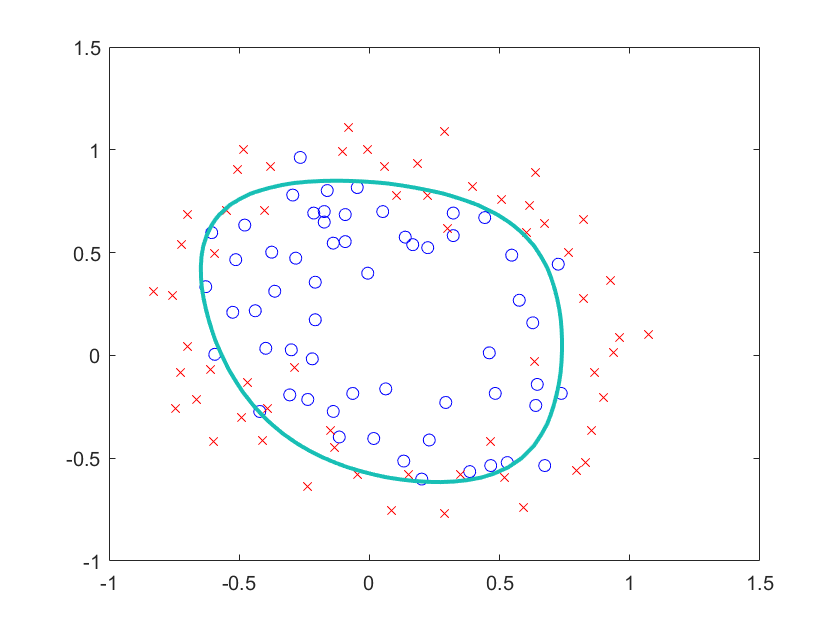


% Plot Boundar
plot(aa(pos, 1), aa(pos, 2), 'bo')
hold on
plot(aa(neg, 1), aa(neg, 2), 'rx')
hold on
plotDecisionBoundary(theta, X, y);
hold off

function [J, grad] = costFunctionReg(theta, X, y, lambda)
%COSTFUNCTIONREG Compute cost and gradient for logistic regression with regularization
%   J = COSTFUNCTIONREG(theta, X, y, lambda) computes the cost of using
%   theta as the parameter for regularized logistic regression and the
%   gradient of the cost w.r.t. to the parameters. 

m = length(y); % number of training examples

J = 0;
grad = zeros(size(theta));

hypothesis = sigmoid(X*theta);
J = binary_crossentropy(hypothesis, y)+(lambda/(2*m))*sum(theta.*theta);
grad = (1/m)*(X'*(hypothesis-y)+lambda*(theta)');
grad(1) = (1/m)*(sum((hypothesis-y).*X(1)));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function out = mapFeature(X1, X2)
% MAPFEATURE Feature mapping function to polynomial features
%
%   MAPFEATURE(X1, X2) maps the two input features
%   to quadratic features used in the regularization exercise.
%
%   Returns a new feature array with more features, comprising of 
%   X1, X2, X1.^2, X2.^2, X1*X2, X1*X2.^2, etc..
%
%   Inputs X1, X2 must be the same size
%

degree = 6;
out = ones(size(X1(:,1)));
for i = 1:degree
    for j = 0:i
        out(:, end+1) = (X1.^(i-j)).*(X2.^j);
    end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function[sig] = sigmoid(x)
    sig = 1./(1+exp(-x));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%parameters for binary crossentropy loss:%data:activation funct applied
                                         %y: actual output
function[j] = binary_crossentropy(data, y)
    j = sum(-y.*log(data)-(1.-y).*log(1.-data))/length(y);
end
